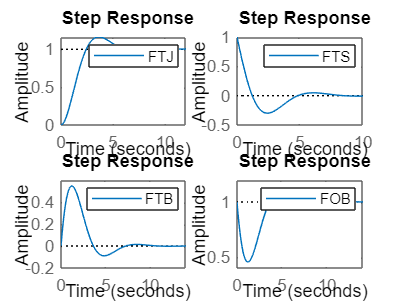

clear variables

R=1;C=1;L=1;% atribuire de valori la parametrii sistemului

ftj=tf(1/L/C,[1 R/L 1/L/C]);% functia de transfer pt. FTJ
fts=tf([1 0 0],[1 R/L 1/L/C]);% functia de transfer pt. FTS
ftb=tf([R/L 0],[1 R/L 1/L/C]);% funcțiade transfer pt. FTB
fob=tf([1 0 1/L/C],[1 R/L 1/L/C]);% funcția de transfer pt. FOB
% răspunsul la treapta pentru FTJ
subplot(221);step(ftj);legend('FTJ');

% răspunsul la treapta pentru FTS
subplot(222);step(fts);legend('FTS');

% răspunsul la treapta pentru FTB
subplot(223);step(ftb);legend('FTB');

% răspunsul la treapta pentru FOB
subplot(224);step(fob);legend('FOB');